# 2.12 Lab 3: Euler Transforms

Create a set of three rotation matrices. One which represents a $\phi=25^\circ$ about the $z$ axis, another which represents a rotation of $\theta=45^\circ$ about the $x$ axis, and a final matrix for $\psi=60^\circ$ about the $z$ axis ($R_{z1}$, $R_x$, $R_{z2}$ respectively). Note that in MATLAB, you can use sind(), cosd(), and tand() with input arguments in degrees instead of radians.

% MODIFY CODE HERE
phi = 25;
theta = 45;
psi = 60;
Rz1 = [cosd(phi) -sind(phi) 0; sind(phi) cosd(phi) 0; 0 0 1;];
Rx = [1 0 0; 0 cosd(theta) -sind(theta); 0 sind(theta) cosd(theta);];
Rz2 = [cosd(psi) -sind(psi) 0; sind(psi) cosd(psi) 0; 0 0 1;];

Now, perform two sets of transformations with these matrices, $R1$ and $R2$. In $R1$, we want to perform the $60^\circ$ rotation about $z$ first, then a $45^\circ$ rotation about the $x$ axis, and then a 25 rotation about the new $z$ axis. In $R2$, you'll perform the $25^\circ$ rotation about the $z$ axis first, then a $45^\circ$ rotation about the $x$ axis, and then a $60^\circ$ rotation about the new $z$ axis. Apply both of these transforms to a coordinate frame with **n** = [1, 0, 0]', **t** = [0, cosd(15), sind(15)]', and **b** = [0,-sind(15), cosd(15)]'. 

Fill out the code below to visualize these two transformations. Note that the red axis represents the coordinate frame's **n** vector, the green axis represents **t**, and the blue axis represents **b**.

**Question:** *Fill out the code below to visualize these two transformations. Note that the red axis represents the coordinate frame's ****n**** vector, the green axis represents ****t****, and the blue axis represents ****b****. What is the orientation of the initial [n,t,b] coordinate frame relative to the world frame?*

**Answer: **The n vector (red) points along the x axis, whereas the t vector (green) and b vector (blue) are rotated along the x-axis by 15 degrees.

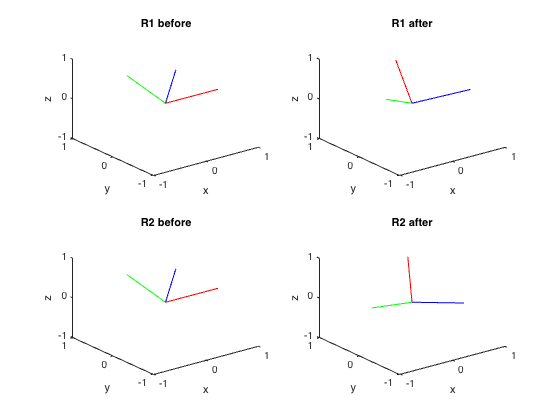

n = [1, 0, 0]';
t = [0, cosd(15), sind(15)]';
b = [0, -sind(15), cosd(15)]';
R0 = [n,t,b];
% MODIFY CODE HERE
R1 = Rz2*Rx*Rz1;
R2 = Rz1*Rx*Rz2;

subplot(2,2,1)
% MODIFY CODE HERE
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation before applying R1, R0))
plotTransforms([0 0 0],rotm2quat(R0))
xlabel('x')
ylabel('y')
zlabel('z')
title('R1 before')
axis([-1 1 -1 1 -1 1])

subplot(2,2,2)
% MODIFY CODE HERE
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation after applying R1, R0*R1))
plotTransforms([0 0 0],rotm2quat(R0*R1))
xlabel('x')
ylabel('y')
zlabel('z')
title('R1 after')
axis([-1 1 -1 1 -1 1])

subplot(2,2,3)
% MODIFY CODE HERE
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation before applying R2, R0))
plotTransforms([0 0 0],rotm2quat(R0))
xlabel('x')
ylabel('y')
zlabel('z')
title('R2 before')
axis([-1 1 -1 1 -1 1])

subplot(2,2,4)
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation after applying R2, R0*R2))
plotTransforms([0 0 0],rotm2quat(R0*R2))
xlabel('x')
ylabel('y')
zlabel('z')
title('R2 after')
axis([-1 1 -1 1 -1 1])

**Question**: *What are the ****n****, ****t****, and ****b ****vectors for the final coordinate frames? Are they different? Why do these two transformations lead to different orientations? Do you know of any alternate ways that these transformations could be represented?*

**Answer: **

a = R0*R1;

a =     0.1944   -0.7663    0.6124
    0.6597   -0.3599   -0.6597
    0.7260    0.5322    0.4356


n1 = a(:,1)

n1 =     0.1944
    0.6597
    0.7260


t1 = a(:,2)

t1 =    -0.7663
   -0.3599
    0.5322


b1 = a(:,3)

b1 =     0.6124
   -0.6597
    0.4356



b = R0*R2;

b =     0.1944   -0.9343    0.2988
    0.3575   -0.2162   -0.9086
    0.9135    0.2834    0.2919


n2 = b(:,1)

n2 =     0.1944
    0.3575
    0.9135


t2 = b(:,2)

t2 =    -0.9343
   -0.2162
    0.2834


b2 = b(:,3)

b2 =     0.2988
   -0.9086
    0.2919


Yes, they are different because each rotation builds on the previous one therefore the order the rotations are performed matters. Another way that these transformations could be represented is with roll, pitch, and yaw: which occur along the x, y, and z axis.

Version 1: Cormac O'Neill, 2021